clc
clearvars
close all

set(0, 'DefaultFigureWindowStyle', 'normal');

## Governing Equations


$$T_{motor} = T_{dyn} + T_{fric.} + K_{Harness} \theta$$


### Motor Graph Equation

$n(T) = n_{0L} - \frac{n_{0L}}{T_{stall}} \cdot T}$ - nominal working point

$n_{Us}(T_{Us}) = k_nU_s-\frac{n_{0L}}{T_{stall}}\cdot T_{Us}$ - for supply voltage

$k_n min = \frac{n_{wp} + \frac{n_{0L}}{T_{stall}}\cdot T_{wp}}{U_s}$ - winding req. for supply voltage

### Sine Motion


$$\alpha_{dyn} = \omega(2 \pi f) \Rightarrow \\
T_{dyn} = \omega J(2 \pi f)
$$


### Bang Bang Motion


$$\frac{\theta_{BANG}}{2} = \frac{1}{2}\alpha \cdot \Big(\frac{t_{BANG}}{2}\Big)^2
\rightarrow
\alpha = \frac{4 \theta_{BANG}}{t_{BANG}^2}\\
\Rightarrow
\omega_{max} = \frac{2\theta_{BANG}}{t_{BANG}} \\
\Rightarrow
T_{dyn} = \frac{4J\theta_{BANG}}{t_{BANG}^2}$$


### Constant Rate Motion


$$T_{dyn} = 0$$


## Requirements

### Power Supply

Us = 12.0; %[V]

### Payload Dynamics

- Sine profile

payloadSineFreq = 2; %[Hz]
payloadSineVel = deg2rad(50); %[dps]

        2. Bang-Bang profile

payloadBangAngle = deg2rad(20); %[deg]
payloadBangPeriod = 0.5; %[sec]

        3. Constant speed profile

payloadConstRate = deg2rad(20); %[deg/s]

        4. Single point

payloadSPvel = deg2rad(16.1); %[dps]
payloadSPacc = 0.4; %[rad/s^2]

### **Plant properties**

Jp = 105e-6; %[kgm^2]
Jm = 1e-6; %[kgm^2]
N_ref = 70;
Tfric = 15e-3; %[Nm]
Kharness = 50.0e-3; %[Nm/Rad]
Travel = deg2rad(20); %[deg]
angleLimit = deg2rad(20); %[rad]

J = Jp + N_ref^2*Jm;

## Motion Profiles

- Sine Motion

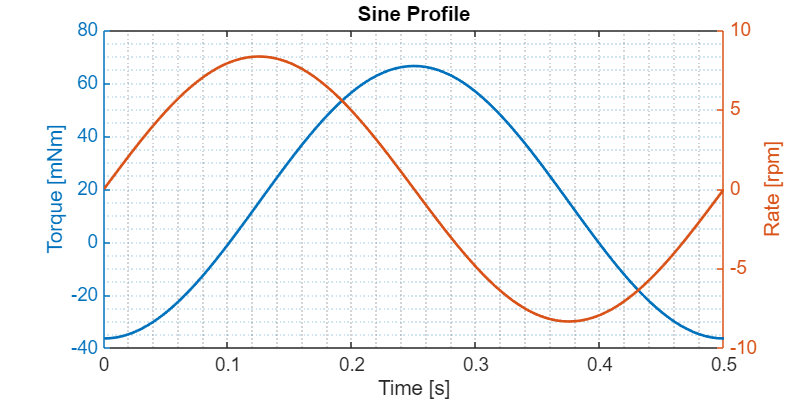

tsS = 0:1/payloadSineFreq/100:1/payloadSineFreq;
% sine motion

thetasSine = payloadSineVel/(2*pi*payloadSineFreq)*cos(2*pi*payloadSineFreq*tsS);
wsSine = payloadSineVel*sin(2*pi*payloadSineFreq*tsS);
alphasSine = payloadSineVel*(2*pi*payloadSineFreq)*cos(2*pi*payloadSineFreq*tsS);
TdynSine = - J*alphasSine;
TSine = TdynSine + Tfric + Kharness*thetasSine;

figure('Position',[0 0 800 400])
title('Sine Profile')
yyaxis left
plot(tsS, TSine*1e3, 'LineWidth', 2.0)
ylabel('Torque [mNm]', 'Interpreter','tex')
xlabel('Time [s]')
yyaxis right
plot(tsS, wsSine*(30/pi), 'LineWidth', 2.0)
ylabel('Rate [rpm]')
grid minor
set(gca, 'FontSize', 14);

        2. BANG-BANG Motion

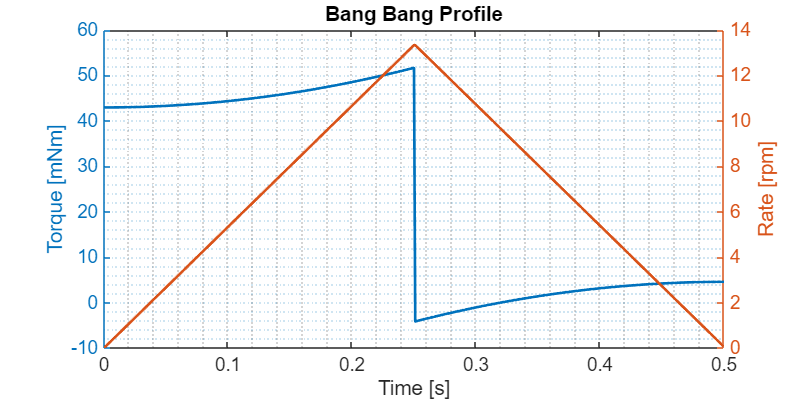

tsB = 0:0.001:payloadBangPeriod;
% bang bang
alphasBang = ones(size(tsB));
alphasBang(tsB <= payloadBangPeriod/2) = 4*payloadBangAngle/payloadBangPeriod^2;
alphasBang(tsB > payloadBangPeriod/2) = -4*payloadBangAngle/payloadBangPeriod^2;
wsBang = cumtrapz(tsB, alphasBang);
thetasBang = cumtrapz(tsB, wsBang);
Tdynbang = J*alphasBang;
TBang = Tdynbang + Tfric + Kharness*thetasBang;

figure('Position',[0 0 800 400])
title('Bang Bang Profile')
yyaxis left
plot(tsB, TBang*1e3, 'LineWidth',2.0)
ylabel('Torque [mNm]')
xlabel('Time [s]')
yyaxis right
plot(tsB, wsBang*(30/pi), 'LineWidth', 2.0)
ylabel('Rate [rpm]')
set(gca, 'Fontsize', 14)
grid minor

        3. Constant speed

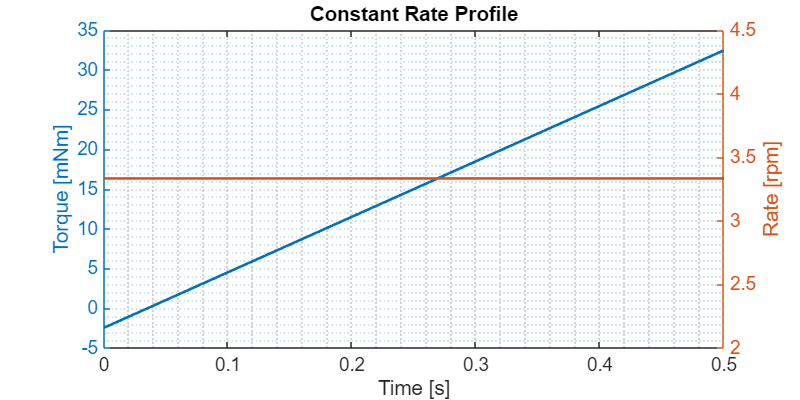

% constant rate
TdynConstRate = zeros(size(tsB));
thetasConstRate = linspace(-angleLimit, angleLimit, numel(tsB));
TConstRate = TdynConstRate + Tfric + Kharness*thetasConstRate;
wsConstRate = payloadConstRate * ones(size(tsB));

figure('Position',[0 0 800 400])
yyaxis left
plot(tsB, TConstRate*1e3, 'LineWidth', 2.0)
title('Constant Rate Profile')
ylabel('Torque [mNm]')
xlabel('Time [s]')

yyaxis right
plot(tsB, wsConstRate*(30/pi), 'LineWidth',2.0)

ylabel('Rate [rpm]')
set(gca, 'Fontsize', 14)
grid minor

        4. Single point

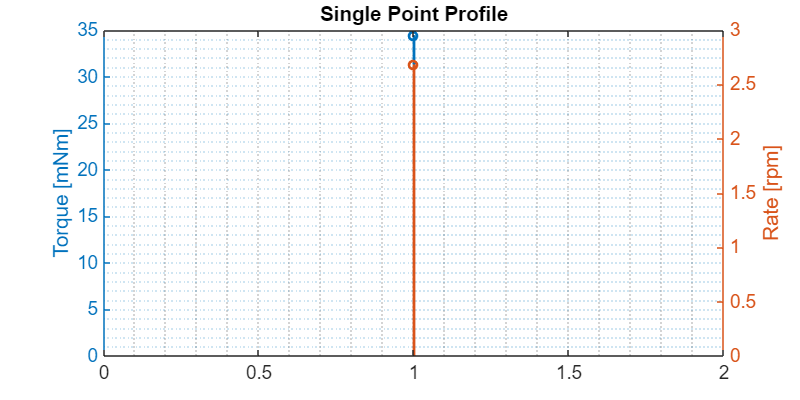

TdynSP = J*payloadSPacc;
TSP = TdynSP + Tfric + Kharness*angleLimit;
wsSP = payloadSPvel;

figure('Position',[0 0 800 400])
yyaxis left
stem(TSP*1e3, 'LineWidth', 2.0)
title('Single Point Profile')
ylabel('Torque [mNm]')

yyaxis right
stem(wsSP*(30/pi), 'LineWidth',2.0)

ylabel('Rate [rpm]')
xlim([0 2 ])
set(gca, 'Fontsize', 14)
grid minor

### Motion Requirement Summary

Torque_mNm = [max(abs(TSine)); max(abs(TBang)); max(abs(TConstRate)); max(abs(TSP))]*1e3;
speed_rpm = [max(abs(wsSine)); max(abs(wsBang)); max(abs(payloadConstRate));max(abs(wsSP))]*(30/pi);
power_W = [max(abs(TSine.*wsSine)); max(abs(TBang.*wsBang)); max(abs(TConstRate.*wsConstRate));max(abs(TSP.*wsSP))];

T = table(Torque_mNm, speed_rpm, power_W,...
    'RowNames', {'Sine';'Bang';'Constant';'Single Point'})

T = 4×3 table
                    Torque_mNm    speed_rpm     power_W 
                    __________    _________    _________

    Sine              66.414       8.3333       0.032122
    Bang               51.68       13.333       0.072159
    Constant          32.453       3.3333       0.011328
    Single Point      34.455       2.6833      0.0096819


[~, ind] = max(power_W);

Twp_pay = Torque_mNm(ind); %[Nmm]
nwp_pay = speed_rpm(ind); %[rpm]
power_pay = power_W(ind); %[W]

fprintf( ['Max. Torque is: %.1f [mNm] \n' ...
    'Max. Rate is: %.1f [rpm] \n' ...
    'Max. Power is: %.3f [W] \n' ], Twp_pay, nwp_pay,  power_pay);

Max. Torque is: 51.7 [mNm] 
Max. Rate is: 13.3 [rpm] 
Max. Power is: 0.072 [W] 


## Motor + Gear Selection

% motor curve
Tstall = 1.0; %[mNm]
n0L = 11600; %[rpm]
eff = 75/100;

N = 70;

figure('Position',[0 0 600 300])
hold on
title('Motor Selection Curve');

### Requirements

plot(abs(TSine/N)*1e3/eff, abs(wsSine*N)*(30/pi), '*', 'DisplayName', 'Sine');
plot(abs(TBang/N)*1e3/eff, abs(wsBang*N)*(30/pi), 'p', 'DisplayName', 'BANG');
plot(abs(TConstRate/N)*1e3/eff, wsConstRate*N*(30/pi), 'o', 'DisplayName', 'Const');
stem(abs(TSP/N)*1e3/eff, wsSP*N*(30/pi), 'filled', 'DisplayName','singlePoint', 'MarkerSize',10);
stem(abs(Twp_pay/N)/eff, nwp_pay*N, 'filled', 'DisplayName','WP', 'MarkerSize',10);

### Motor Curve

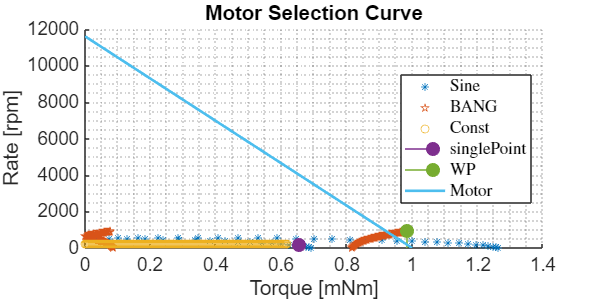

plot([0 Tstall],[n0L 0], 'LineWidth',2, 'DisplayName', 'Motor');

lgd = legend('show', 'Interpreter', 'latex', 'Location', 'best');
lgd.ItemHitFcn = @(~, evt) toggleLineVisibility(evt);

xlabel('Torque [mNm]')
ylabel('Rate [rpm]')

set(gca, 'Fontsize', 14)
grid minor

### Windings Advisor

Twp_mot = Twp_pay/N/eff;
nwp_mot = nwp_pay*N;


grad = n0L/Tstall;
kn_min = 1.2*(nwp_mot + grad*Twp_mot)/Us;
fprintf('Minimum required kn for Us of %d [V] : %.1f [rpm/V]', Us, kn_min);

Minimum required kn for Us of 12 [V] : 1235.2 [rpm/V]

### Selected Kn

kn_sel =1294.7; %[rpm/V]

n0L_Us = kn_sel*Us;
Tstall_Us = n0L_Us/grad;

### Selection Verifier

figure('Position',[0 0 600 300])
hold on
title(sprintf('Windings Selection Curve - kn of %.1f [rpm/V]', kn_sel));

plot(abs(TSine/N)*1e3/eff, abs(wsSine*N)*(30/pi), '*', 'DisplayName', 'Sine');
plot(abs(TBang/N)*1e3/eff, abs(wsBang*N)*(30/pi), 'p', 'DisplayName', 'BANG');
plot(abs(TConstRate/N)*1e3/eff, wsConstRate*N*(30/pi), 'o', 'DisplayName', 'Const');
stem(abs(TSP/N)*1e3/eff, wsSP*N*(30/pi), 'filled', 'DisplayName','singlePoint', 'MarkerSize',10);
stem(abs(Twp_pay/N)/eff, nwp_pay*N, 'filled', 'DisplayName','WP', 'MarkerSize',10);

### Adapted Motor Curve for Limited - Us

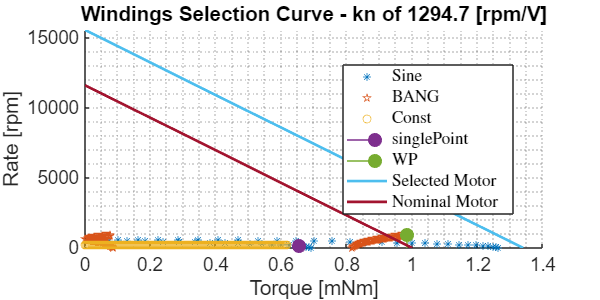

plot([0 Tstall_Us],[n0L_Us 0], 'LineWidth',2, 'DisplayName', 'Selected Motor');
plot([0 Tstall],[n0L 0], 'LineWidth',2, 'DisplayName', 'Nominal Motor');

lgd = legend('show', 'Interpreter', 'latex', 'Location', 'best');
lgd.ItemHitFcn = @(~, evt) toggleLineVisibility(evt);

xlabel('Torque [mNm]')
ylabel('Rate [rpm]')

set(gca, 'Fontsize', 14)
grid minor

I_max = (Twp_mot)/((kn_sel/(30/pi))^-1*1e3 );
fprintf('Required current @wp for Us=%d [V] : %.3f [A]', Us, I_max);

Required current @wp for Us=12 [V] : 0.133 [A]

% set(0, 'DefaultFigureWindowStyle', 'docked');